# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Prerequisites

### Software Prerequisites

#### SNAP ESA

SNAP is a tool developed by the European Space Agency (ESA) to process SAR data obtained from Sentinel Satellites. SNAP is used to pre-process data in this pipeline and is essential to install.

To install SNAP please do the following:

- Download SNAP [here](https://step.esa.int/main/download/snap-download/) for your OS distribution

- Choose only the Sentinel Toolboxes installer

- Install SNAP and follow the onscreen instructions. It is only necessary to install the Sentinel-1 Toolbox

### MATLAB Prerequisites

#### M_Map

M_Map is a mapping package for MATLAB which allows data plots on different world maps.

To use M_Map please do the following:

- Download the zipped package [here](https://www.eoas.ubc.ca/~rich/map.html#download) and

- Add the extracted folder to your MATLAB path

*Note:* A copy of the M_Map package is included on the [git repo here](https://github.com/JNSRYA006/sar-parameter-extraction-pipeline/tree/main/toolboxes/m_map).

## Obtain SAR Data

[https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf](https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf)

## **Pre-Process SAR Data**

After downloading SAR data from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home), open SNAP and import the data. These data can be viewed as follows:

- Click the '+' next to the dataset

- Click the '+' next to the *Bands* folder

- Open the desired band to preview the image

### Thermal Noise Calibration

**This needs to be done first**

To remove thermal noise, click *Radar -> Radiometric -> S1 Thermal Noise Removal. *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that *Remove Thermal Noise* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin removing thermal noise from the selected data and once complete will open in the *Product Explorer *sidebar.

### Ellipsoid Correction

To radiometrically calibrate the SAR data, ensure that the **noise calibrated product is selected**, then click *Radar -> Geometric -> E *This will bring up a window where the following needs to be done.

### Radiometric Calibration

To radiometrically calibrate the SAR data, ensure that the **noise calibrated product is selected**, then click *Radar -> Radiometric -> Calibrate *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that **only** *Output sigma0 band* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin radiometric calibration from the selected data and once complete will open in the *Product Explorer *sidebar.

## 1 Import the CosmoSkyMED Data

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/MSc/subset_CSKS1_DGM_B_WR_01_VV_RA_SF_20220722070221_20220722070237_small.nc";

ncInfo_SAR = ncinfo(filepath);
% Create a cosmo satellite object to store all important information.
cosmo = CosmoSkyMED(filepath,"CSK");

% Import the data.
%sarData = ncread(cosmo.Filepath,'Amplitude');
sarData = ncread(cosmo.Filepath,'Intensity');
sar_latGrid = ncread(cosmo.Filepath,'lat')';
sar_lonGrid = ncread(cosmo.Filepath,'lon')';

Alternatively, import the data as an hdf5 file.

% filepath = "/Users/tris/Documents/MATLAB/MSc/20220722_1778608_CSG_/CSG_SSAR1_DGM_B_0301_SC1_001_VV_RA_F_20220722065043_20220722065057_1_F_57S_Z31_N00.h5";
% 
% h5Info = h5info(filepath);
% 
% % Create a structure to store imported HDF5 data
% sarData = h5read(filepath, '/IMG');
% % Display results
% figure; imshow(sarData);

### View SAR Data

Choose whether to display a greyscale image of the imported SAR data.

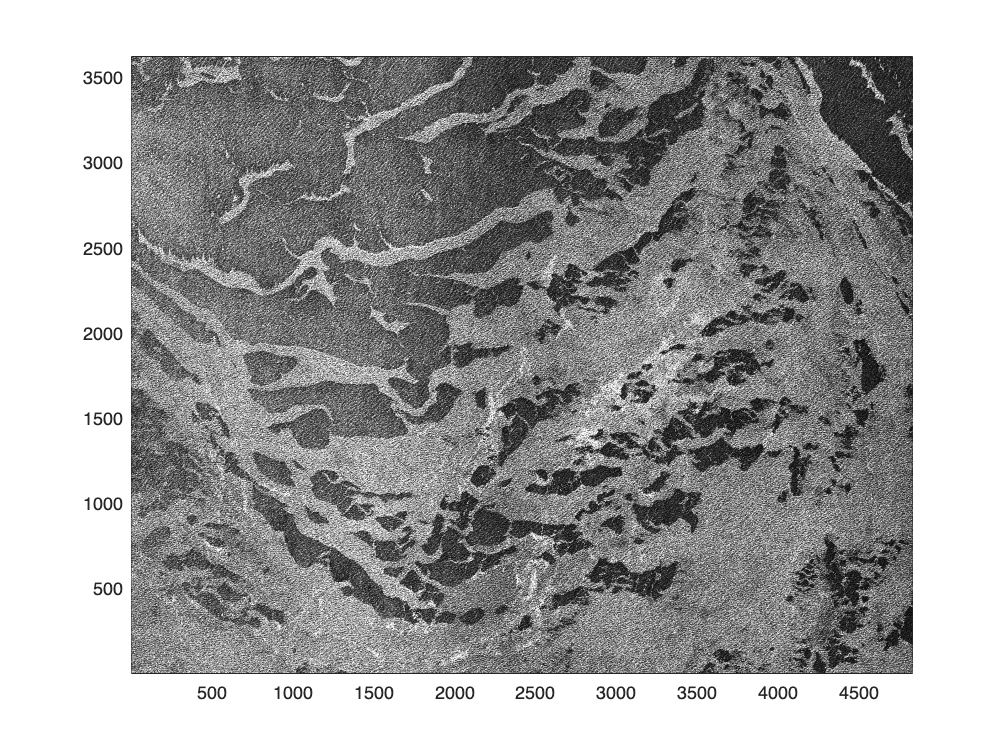

% plotSARData = true;
figure;
pcolor(sarData'/mean(sarData(:)));
shading("flat");
colormap("gray");
clim([0 2]);

### Radiometric Calibration

sarData_cal = cosmo.radiometricCalibration(sarData);

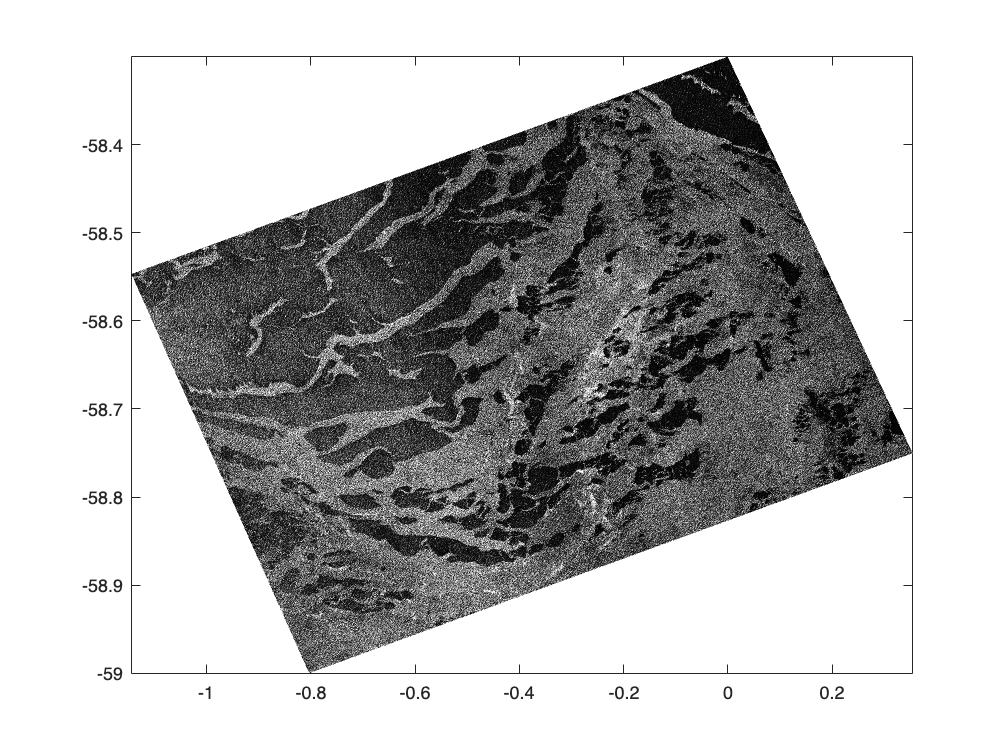

figure;
pcolor(sar_lonGrid,sar_latGrid,sarData_cal'/mean(sarData_cal(:)));
shading("flat");
colormap("gray");
clim([0 2]);

### **Take Transects**

% Plot where the transect will be taken (use original data to view more
% easily

% figure;
% pcolor(sarData'/mean(sarData(:)));
% shading("flat");
% colormap("gray");
% clim([0 2]);
% hold on
% plot([512 512],[0 3621],'r');
% plot([0 4834],[3200-512 3200-512],'b');
% plot([0 4834],[3200 3200],'b');

Now subset the calibrated data to produce a transect.

sar_transect_size =  512;

% Calculate the transect from the calibrated data
sar_transect = sarData_cal(1:sar_transect_size, (3200-sar_transect_size):3200-1);

% % Plot the transect
% figure;
% pcolor(transect'/mean(transect(:)));
% shading("flat");
% colormap("gray");
% clim([0 2]);

## 2 ERA5 Data

### 2.1 Download

Get this from the CDS_ERA5_datahandling script. NOTE: Make it adjustable so that the correct date and time data can be downloaded.

### 2.2 Import from file

%% Get Parameters of the complete 
filepath = "/Users/tris/Documents/MATLAB/MSc/ERA5-2Dws_20220720.nc";

% Store file info in MATLAB struct
ncinfo_era5 = ncinfo(filepath);

% Get attributes
era5_lon=ncread(filepath,'longitude');
era5_lat=ncread(filepath,'latitude');
era5_time = ncread(filepath,'time');
era5_direction=ncread(filepath,'direction');
era5_d2fd=ncread(filepath,'d2fd');
era5_d2fd=double(era5_d2fd); % Usually dimensions are: lon lat dir frq time

% freq ERA5 according to https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation
era5_freq_bins = zeros(size(era5_d2fd,4),1);
era5_freq_bins(1)=0.03453;
for i=2:length(era5_freq_bins)
    era5_freq_bins(i) = era5_freq_bins(i-1)*1.1;
end

### **2.3 Define Points of Interest**

These are the points in the single level data (from step 2) that we are interested in view the spectrum of (in step 4).

latitude_of_interest = -55;
longitude_of_interest = -5;
time_of_interest_index = 7;
time_of_interest = era5_time(time_of_interest_index); % this should be the same as the time index chosen in step 2 for all plots.

### **2.4 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

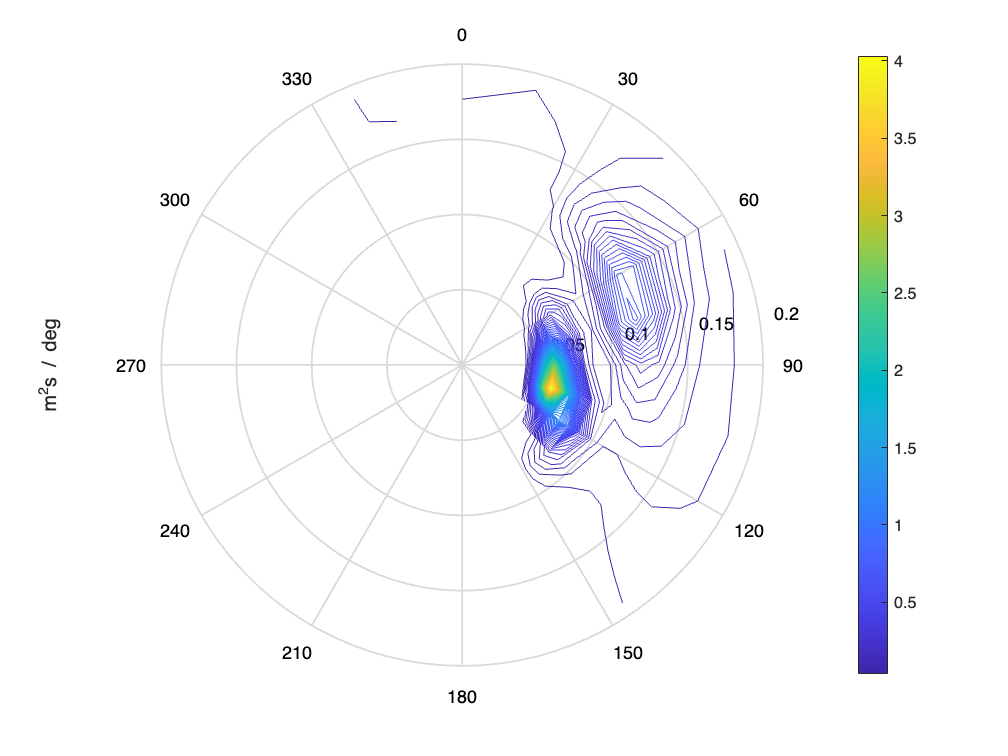

plotERA52Dspectrum = true;
if plotERA52Dspectrum
    % Find the slice that matches what we are plotting in the single level data
    % in step 2.
    time_position_match = find(era5_time == time_of_interest);
    lat_position_match = find(era5_lat == latitude_of_interest);
    lon_position_match = find(era5_lon == longitude_of_interest);
    
    % Plot the 2D spectra
    figure;
    sp(:,:) = 10.^era5_d2fd(lon_position_match,lat_position_match,:,:,time_position_match);
    PolarContour(sp, era5_freq_bins, 0.2);
end 

### Calculate the parameters

% direction integration values according to the ERA5 documentation
era5_direction_bins = (7.5: 15: 352.5)/180*pi; % From ERA5 documentation

#### Significant Height

% Calculate the wave spectrum for all time
era5_spectrum_all_time = zeros(size(era5_d2fd,5),size(era5_d2fd,3),size(era5_d2fd,4)); % dimensions t direc freq
for t = 1:size(era5_d2fd,5)
    era5_d2fd_match(:,:) = era5_d2fd(lon_position_match,lat_position_match,:,:,t); % Dimensions are: direction,frequency
    era5_spectrum_all_time(t,:,:) = 10.^era5_d2fd_match;
    era5_spectrum_all_time(isnan(era5_spectrum_all_time))=0; % Otherwise all values are just N
end

% Calculate the 0th order moments (m_n) [Eq.8]
era5_m0_derived_all_time = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_spectrum_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
era5_Hs_derived_all_time = 4*sqrt(era5_m0_derived_all_time); 

#### Mean wave period

% Calculate the -1st order moments (m_n)
era5_m_neg1_derived_all_time = zeros(size(era5_d2fd,5),1);
for t = 1:size(era5_d2fd,5)
    spectrum(:,:) = era5_spectrum_all_time(t,:,:);
    era5_m_neg1_derived_all_time(t,1) = trapz(era5_direction_bins,trapz(era5_freq_bins,(1/era5_freq_bins).*spectrum,2),1); %[Eq.8]
end

% Calculate the mean wave period (Tm) [Eq.5]
era5_Tm_derived_all_time = era5_m_neg1_derived_all_time./era5_m0_derived_all_time; % [Eq.5]

#### Mean wave direction

% Calculate the angular moments [Eq.9&10]
for t = 1:size(era5_d2fd,5)
    spectrum(:,:) = era5_spectrum_all_time(t,:,:); % dimenstions: direc, freq
    era5_a1(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins)'.*spectrum,1),2); %[Eq.9]
    era5_b1(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins)'.*spectrum,1),2); %[Eq.10]
end

% Calculate the mean Direction of the wave
era5_direction_derived_all_time = atand(era5_b1./era5_a1); %[Eq.6]

### 2.5 Plot Wave Direction

% Plot the Lat-Long x-y grid 
[era5_lonGrid, era5_latGrid] = meshgrid(era5_lon,era5_lat);

% Convert angles to radians
era5_angle_rad = deg2rad(era5_direction_derived_all_time(time_position_match));

% Plot the grid (optional, for context)
figure;
plot(era5_lonGrid, era5_latGrid, "k+");  % Plot grid points for reference
hold on;
% Plot the directional arrow at the specific latitude and longitude
quiver(longitude_of_interest, latitude_of_interest, cos(era5_angle_rad), sin(era5_angle_rad), ...
       'AutoScale', 'off', 'MaxHeadSize', 2, 'LineWidth', 2, 'Color', 'r');

% Adjust plot settings
title('Directional Arrow at Specific Location of Wave Spectrum');
xlabel('Longitude');
ylabel('Latitude');
axis equal;  % Ensure equal scaling of axes
grid on;
grid minor;
hold off;

# Open Ocean H&H

% Import the functions
handh = hAndH1991Functions;

% Import the SAR metadata attributes
metadata_attributes = ncinfo(cosmo.Filepath,'Metadata_Group').Groups(1).Attributes;


[~,matching_row_number] = ismember("mds1_tx_rx_polar", {metadata_attributes.Name});
polarisation = metadata_attributes(matching_row_number(1)).Value;
sar_polarisation = polarisation;

incidence_angle = ncread(cosmo.Filepath,"incident_angle");
teta1 = incidence_angle(sar_transect_size/2, sar_transect_size/2);
sar_center_incidence_angle_degrees = teta1; % center of the transect

g = 9.81;

% [pg43, Hasselmann, 1990] - "...in all cases as mu = 0.5 1/sec and gamma = 0.
% This is consistent qith field and laboratory measurements (cf. Keller and
% Wright, 1975)"
mu = 0.5;


[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
dy = metadata_attributes(matching_row_number(1)).Value;
[~,matching_row_number] = ismember("azimuth_spacing", {metadata_attributes.Name});
dx =metadata_attributes(matching_row_number(1)).Value;

% From Giacomo's code:
dk = (2*pi)/(dx*sar_transect_size);
kx = -pi / dx + (1:sar_transect_size) * dk;
ky = kx';

% Formulae are correct [Holtjuisen]
k = sqrt(kx.^2 + ky.^2);
omega = sqrt(k/g); 
minimum_wavelength = 2*pi./max(k); %[m]

% Get the k_l variable using the direction of the SAR look.
[~,matching_row_number] = ismember("antenna_pointing", {metadata_attributes.Name});
sar_look = metadata_attributes(matching_row_number(1)).Value;
[sar_look,kl] = handh.klUsingSARlook(sar_look,ky);

## Sar Imaging of Ocean Waves

### Frozen Surface Contribution

Tt_k = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees, kl);
Th_k = handh.hydrodynamicMTF(omega, mu, k, ky);
TR_k = handh.rarMTF(Tt_k,Th_k);

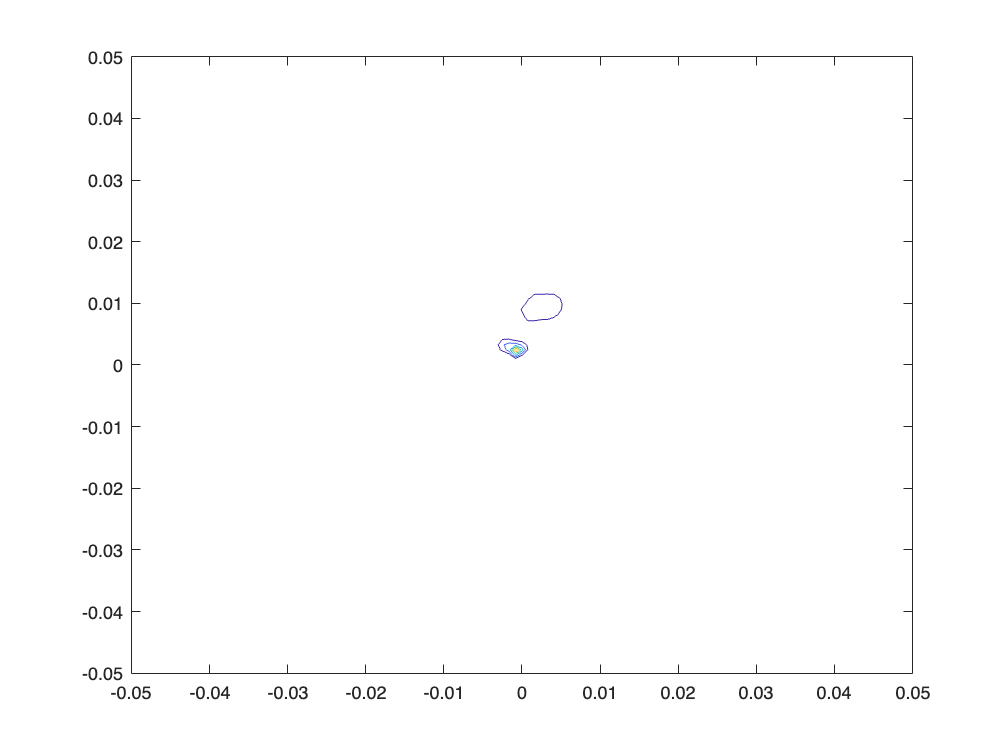

era5_spectrum(:,:) = 10.^era5_spectrum_all_time(time_position_match,:,:);


era5_direction_bins = (7.5: 15: 352.5)/180*pi; % From ERA5 documentation

% Francesca's code for interpolation of the ERA5 data to the size of the
% SAR transect (email = 26 Jul @ 14:07)
[F, D] = meshgrid(era5_freq_bins, era5_direction_bins);
era5_k = (2 * pi * F.^2) / g; % era5_k= ((2*pi*era5_freq_bins).^2)./g; % deep water approcimation of the wave number
era5_kx = era5_k .* cos(D); % era5_kx = era5_k .* cos(era5_direction_bins);
era5_ky = era5_k .* sin(D); % era5_ky = era5_k .* sin(era5_direction_bins);

% Interpolate the spectrum onto a regular grid in kx and ky
kx_min = min(era5_kx(:));
kx_max = max(era5_kx(:));
ky_min = min(era5_ky(:));
ky_max = max(era5_ky(:));
kx_grid = linspace(kx_min, kx_max, size(era5_spectrum, 1));
ky_grid = linspace(ky_min, ky_max, size(era5_spectrum, 2));

% Interpolate the spectrum
era5_spectrum_kxky = griddata(era5_kx, era5_ky, sp, kx, ky, 'linear');

% Handle NaN values (optional)
era5_spectrum_kxky(isnan(era5_spectrum_kxky)) = 0;

figure;
contour(kx, ky,era5_spectrum_kxky);
xlim([-0.05 0.05]);
ylim([-0.05 0.05]);
shading("flat");

% 
% % Ocean surface
% era5_spectrum_kxky_ifft = ifft(era5_spectrum_kxky);
% pcolor(abs(era5_spectrum_kxky_ifft));
% shading("flat");

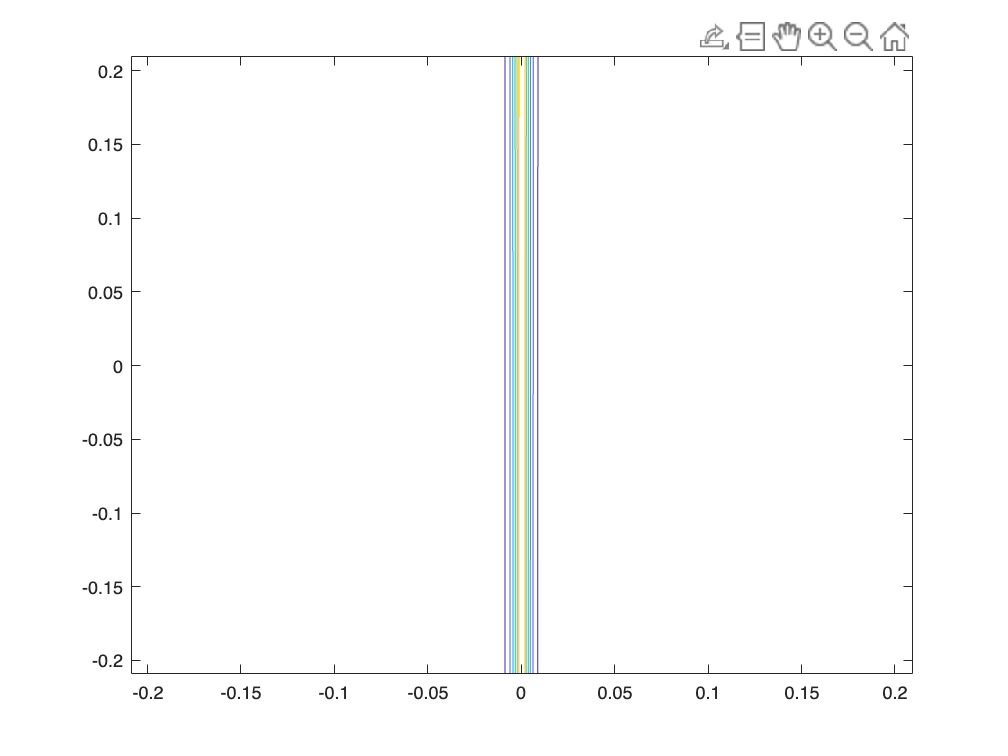

x = (0:511)*dx;
y = x';
r = sqrt(x.^2+y.^2);

nonLinOrder = 1;
n = nonLinOrder;
% Calc beta
[~,matching_row_number] = ismember("slant_range_to_first_pixel", {metadata_attributes.Name});
slant_range = metadata_attributes(matching_row_number(1)).Value;
platform_velocity = 7541.89; %m/s from Giacomo's output file.
beta = slant_range/platform_velocity;

Tv_k = handh.rangeVelocityTF(omega, sar_center_incidence_angle_degrees, kl, k);
Tv_k(isnan(Tv_k)) = 0; % Need to remove NaN values

% Orbital velocity
fv_r = trapz(kx,trapz(ky, era5_spectrum_kxky*abs(Tv_k).^2.*exp(1i.*k.*r),2),1);

% rarImageIntensityAutocovariance [Eq.47]
TR_k(isnan(TR_k)) = 0;
era5_spectrum_kxky_comp = flipud(fliplr(era5_spectrum_kxky));
TR_k_comp = fliplr(TR_k); % same as the code below:
% Tt_k_neg = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees, -1*kl);
% Th_k_neg = handh.hydrodynamicMTF(omega, mu, -1*k, -1*ky);
% TR_k_inv_test = handh.rarMTF(Tt_k,Th_k);
fR_r = 0.5 * trapz(kx, trapz(ky,((era5_spectrum_kxky.*abs(TR_k).^2)+(era5_spectrum_kxky_comp.*abs(TR_k_comp).^2)).*exp(1i.*k.*r),2),1);

%rarImageIntensityCovariance [Eq.48]
%Tv_k_comp = fliplr(Tv_k);
Tv_k_comp = handh.rangeVelocityTF(omega, sar_center_incidence_angle_degrees, -kl, -k);

fRv_r = 0.5 * trapz(kx,trapz(ky,((era5_spectrum_kxky.*TR_k.*conj(Tv_k))+(era5_spectrum_kxky_comp.*conj(TR_k_comp)).*Tv_k_comp).*exp(1i.*k.*r),2),1);

% Velocity Bunching MTF
Tvb_k = -1i*beta*kx*Tv_k; %[Eq.24]

% SAR Imaging MTF
TS_k = TR_k+Tvb_k; %[Eq.27]

xi_squared = beta^2 * trapz(kx,trapz(ky,abs(Tv_k)^2 * era5_spectrum_kxky ,2),1);

% Spectral expansion PS_1
Tvb_k_comp = -1i*beta*-kx*Tv_k_comp;
Tvb_k_comp(isnan(Tvb_k_comp)) = 0; % Handle NaN values (optional)
TS_k_comp = TR_k_comp+Tvb_k_comp;
TS_k_comp(isnan(TS_k_comp)) = 0; % Handle NaN values (optional)
PS_k_1 = (abs(TS_k).^2 * era5_spectrum_kxky./2) + (abs(TS_k_comp).^2 *era5_spectrum_kxky_comp./2); %[Eq.26]
PS_k_1(isnan(PS_k_1)) = 0; % Handle NaN values (optional)

% Quasilinear estimation
PS_ql_k = exp(-kx.^2.*xi_squared).*PS_k_1;% [Eq.56]
PS_ql_k(isnan(PS_ql_k)) = 0; % Handle NaN values (optional)

figure;
contour(kx,ky,PS_ql_k);
shading("flat");

% Inversion
% [Eq.52]




% % Spectral expansion [Eq.51]
% PS_n_2n = fft2((fv_r.^n)/factorial(n)); % Ryan added fftshift?
% 
% % spectralExpansion2n_1 [Eq.52]
% fRv_r_comp = 0.5 * trapz(kx,trapz(ky,((era5_spectrum_kxky.*TR_k.*conj(Tv_k))+(era5_spectrum_kxky_comp.*conj(TR_k_comp)).*Tv_k_comp).*exp(1i.*k.*-r),2),1);
% numerator = 1i * (fRv_r - fRv_r_comp) * fv_r^(n-1);
% PS_n_2nminus1 = fft2(numerator./factorial(n-1));
% 
% % spectralExpansion2n_2 [Eq.53]
% term1 = 1/factorial(n-1)* fR_r * fv_r^(n-1);
% fRv_0 = fRv_r(1,1);
% term2 = 1/factorial(n-2) * (fRv_r-fRv_0) * (fRv_r_comp-fRv_0)*fv_r^(n-1);
% PS_n_2nminus2 = fft2(term1+term2);
% 
% % For n = 1 
% term1 = (kx*beta).^(2*n)*PS_n_2n; % For n = 1 then m = 2(1) = 2 
% term2 = (kx*beta)^(2*n-1)*PS_n_2nminus1; % For n = 1 then m = 2(1)-1 = 1 
% term3 = (kx*beta)^(2*n-2)*PS_n_2nminus2; % For n = 1 then m = 2(1)-2 = 0




%P_generated = generateSARSpectrumOceanWaves(k,ky,kx,era5_spectrum_kxky,-1*era5_spectrum_kxky,sar_center_incidence_angle_degrees,r,nonLinOrder,beta,Tv_k,-1*Tv_k,TR_k,-1*TR_k);

## 3 Open Ocean Inversion

first_guess_2D_directional_spectrum(:,:) = 10.^era5_d2fd(1,2,:,:,7);

% Get rid of the NaN values 
theta=7.5:15:360;
x=theta*pi/180;
d1sp=zeros(size(era5_freq_bins));
% d1sp=trapz(theta*pi/180,first_guess_2D_directional_spectrum(:,1));
for i=1:length(era5_freq_bins)
    y=first_guess_2D_directional_spectrum(:,i);
    x_no_nan = x(~isnan(y));
    y_no_nan = y(~isnan(y));
    if length(y_no_nan)>1
        d1sp(i)=trapz(x_no_nan,y_no_nan);
    elseif length(y_no_nan)==1
        d1sp(i)=y_no_nan;
    else
        d1sp(i)=nan;
    end
end

%temp = first_guess_2D_directional_spectrum
S = d1sp; % 1D directional wave spectrum

% From Ryan's code
w = linspace(0,2*pi,sar_transect_size);
numTransects =1;
transectData = sar_transect;

Start of Ryan's code

% Spectral bandwidth calculation
func = helperFunctions;
multipleWaveSpectra = 0;
if multipleWaveSpectra
    S_1 = S(:,:,5);
else
    S_1 = S;
end
S_1 = S_1(2:end);
S_1 = func.resize(S_1(2:end),w);
for i=2:length(w)
    dw(i) = w(i)-w(i-1);
end
dw = mean(dw);
S_norm = S_1 / (trapz(S_1).*dw);
spectralMean = trapz(w.*S_norm).*dw;
spectralVar = trapz((w-spectralMean).^2.*S_norm).*dw;
spectralBW = sqrt(spectralVar);
plotTransectSARSpectrum = true;
transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

spectrumThreshold =256; 
%57 has been good previously
if plotTransectSARSpectrum
    disp('Generating plot...');
    for i = 1:length(transectsToPlot)
        transectNum = transectsToPlot(i);
        intensityFFT = abs(fftshift(fft2(transectData(:,:,transectNum))));
        SARSpectrumPlot(intensityFFT,spectrumThreshold,spectralBW,1);
        title(['Transect ', num2str(transectNum),' observed SAR Spectrum'])
        %matlab2tikz(['../plots/results/observedSARSpectrum_',num2str(i),'.tex'])
    end
    disp('Done');
end    

Calculate the observed SAR spectrum

observed_sar_spectrum = fftshift(fft2(sar_transect));

% Plot the observed SAR spectrum P_obs.
figure;
contour(20*log10(abs(observed_sar_spectrum)));
colormap('jet');
cb = colorbar;  % create and label the colorbar
clim([70 130]);
view(2);
shading('flat');

Get a bunch a parameters needed by Giacomo's code

P_obs1 = observed_sar_spectrum;
S_guess = first_guess_2D_directional_spectrum;

incidence_angle = ncread(cosmo.Filepath,"incident_angle");
teta1 = incidence_angle(sar_transect_size/2, sar_transect_size/2);

metadata_attributes = ncinfo(cosmo.Filepath,'Metadata_Group').Groups(1).Attributes; 
[~,matching_row_number] = ismember("line_time_interval", {metadata_attributes.Name});
look_sep = metadata_attributes(matching_row_number(1)).Value;

[~,matching_row_number] = ismember("slant_range_to_first_pixel", {metadata_attributes.Name});
slant_range = metadata_attributes(matching_row_number(1)).Value;
platform_velocity = 7541.89; %m/s from Giacomo's output file.

beta1 = slant_range/platform_velocity;

[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
drange = metadata_attributes(matching_row_number(1)).Value;
[~,matching_row_number] = ismember("azimuth_spacing", {metadata_attributes.Name});
dazimuth =metadata_attributes(matching_row_number(1)).Value;

% From Ryan's code
g = 9.81;
k = (w.^2./g)';
kx = k.*cos(era5_direction_derived_all_time(time_position_match));
ky = (k.*sin(era5_direction_derived_all_time(time_position_match)))';
kran = ky;
kaz = kx ;

% Giacomo params again
lc_obs = 155.277; % Form Giacomo code
modk = sqrt(kran.^2 + kaz.^2); % From Giacomo's code (essentially = k)
nn = sar_transect_size;
[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
pixel_size = metadata_attributes(matching_row_number(1)).Value;

ddx = 15; % pixel size in meters
lin_ord = 20; % from Giacomo code

The MTFs

incidenceAngle = teta1;
% Ryan's code
% get metadata
func = helperFunctions;
[~,matching_row_number] = ismember("antenna_pointing", {metadata_attributes.Name});
sar_look = metadata_attributes(matching_row_number(1)).Value;
if(isequal(sar_look,"right"))
    sar_look = 0;
    kl = -1*ky;
else
    sar_look =1;
    kl = ky;
end

[~,matching_row_number] = ismember("mds1_tx_rx_polar", {metadata_attributes.Name});
polarisation = metadata_attributes(matching_row_number(1)).Value;

beta = beta1;

mu =0.5;
omega = abs(sqrt(g.*k));

Tv_k = -1*omega.*(sind(incidenceAngle).*(kl./abs(k)) + 1i.*cosd(incidenceAngle)); %  rangeVelocityTF
Tvb_k = -1i.*beta.*kx.*Tv_k; % Velocity bunching MTF


if(strcmp(polarisation, 'VV') && incidenceAngle<=60)
    Tt_k = 4i * kl * cotd(incidenceAngle) *(1 +sind(incidenceAngle)^2)^(-1); 
elseif (strcmp(polarisation, 'HH'))
    Tt_k = 8i*kl*(sind(2*incidenceAngle))^(-1); 
end

Th_k = (omega-1i.*mu)./(omega.^2+mu.^2).*(4.5).*k.*omega.*((ky.^2)./(k.^2)); % Hydrodynamic MTF
TR_k = Tt_k + Th_k; % RAR MTF


% SOME DERIVATION
% In Ryan's code: Ts_k = TR_k + Tvb_k;  and Tvb_k = -1i.*beta.*k_x.*Tv_k;
% In Giacomo's code: Ts_k = Ti - i * beta_ * kaz .* Ty;
% Therefore:

Ti = TR_k;
Ty = Tvb_k;

% Generate the SAR spectrum of the ERA5 data using Ryan's function
r = ones(size(incidenceAngle));
P_generated = generateSARSpectrumOceanWaves(k,ky,kx,first_guess_2D_directional_spectrum,-1*first_guess_2D_directional_spectrum,incidenceAngle,r,nonLinOrder,beta,Tv_k,-1*Tv_k,TR_k,-1*TR_k);
P_guess = P_generated;


% Procedure for SAR inversion in open sea using HH91 method.
% INPUTS:
% P_SAR  --> observed SAR spectrum (complex if LOOK_SEP > 0)
% S_INP  --> input first guess ocean wave spectrum
%
% OUTPUTS:
% S_OUT --> output best fit ocean wave spectrum
% P_OUT --> corresponding SAR spectrum to S_BEST

% function [S_OUT, P_OUT] = invert_sea_HH91(S_INP, rg_res)

% Define paths
% Add paths for required directories
% addpath('H:\ICE-ARC\Procedure CROSS\Procedure Inversioni SAR\open sea');
% addpath('H:\Odden97\vento_marzo');

% Common variables
% global nn ddx dk kran kaz modk omega HF_orbital_var
% global look_sar band pol Bragg
% global Uvento fi_rg
% global lin_ord beta1 look_sep
% global P_obs1 teta1 fi_wind_azi lc_obs

% Define integration domain for 2D integrals (instead of using TOTAL)
X = reshape(kran(:,1), [], 1);
kx = X;
Y = reshape(kaz(1,:), [], 1);
ky = Y;

grav = 9.81;  % acceleration due to gravity

lc_smoothed = lc_obs; % HAVE no idea what this is, not used anywhere

% Define wavenumber ring for inversion
k0 = 2 * pi / lc_obs;
anello = single(1 - 1 ./ (1 + (k0 / modk).^5));

% Define Butterworth band-pass filter already applied to the observed spectrum
k0 = 2 * pi / 500;
butterworth = single(1 ./ (1 + (k0 / modk).^20));

beta_ = beta1;  % = R/V -> slant range OVER platform velocity

% First guess directional wave spectrum
S_guess = first_guess_directional_spectrum;

S0 = S_guess;
P_obs = P_obs1;

% SAR imaging parameters
teta = teta1;  % incidence angle at the center of image tile [rad]

i = complex(0, 1);
t = look_sep;  % time interval between two looks in SAR cross spectra
               % t = 0 ==> SAR image co-spectrum

% Define SAR image and image spectrum variables
n = nn;       % size along each direction
dx = ddx;     % pixel size in meters
lin_ord = lin_ord;  % non-linearity order in generating the simulated SAR image spectrum

% MTF wind function (assuming it is a MATLAB function defined elsewhere)
% mtf_wind(Uvento, fi_rg, teta);

% % Initialize Ti and Ty
% Ti = complex(zeros(n, n));
% Ty = Ti;
% 
% % Load Ti.dat and Ty.dat (assuming they are binary files)
% fileID = fopen('Ti.dat', 'r');
% Ti = fread(fileID, [n, n], 'double');
% fclose(fileID);
% 
% fileID = fopen('Ty.dat', 'r');
% Ty = fread(fileID, [n, n], 'double');
% fclose(fileID);

Ts_k = Ti - i * beta_ * kaz .* Ty;
n21 = int32(n / 2) - 1;

xx = conj(Ts_k);
tmp = circshift(xx, -n21);
Ts_k_meno = fft2(tmp) / (n^2);
Ts_k_meno = circshift(Ts_k_meno, n21 + 1);

S_ice = S_guess;

% Assuming other functions like `INT_TABULATED_2D_MIO`, `forward_insieme_range`, 
% `stimo_cut_off` are defined elsewhere in MATLAB
% for example: INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_guess).^2);

mu0 = 1e-1 * max(P_obs(:))^2;
B = 1e-2 * max(S_guess(:));

% Call to forward_insieme_range
% [P_guess, P_nl, cshi, fv_00] = forward_insieme_range(lin_ord, beta_, look_sep, S_guess, rg_res);

% Estimate cut-off
% [lc_ice, err_lc, c, y_fit, x_fit, lag] = stimo_cut_off(P_guess, Nc, n_spec, 'pix_size', dx);

P_guess = single(P_guess) .* butterworth;
disp(['Iteration 0: Lambda cut_off = ', num2str(lc_ice)]);

S_ice = S_guess;
% J_guess = INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs .* (P_obs - P_guess).^2) + ...
%     mu0 * INT_TABULATED_2D_MIO(kx, ky, anello .* (S_ice - S_guess).^2 ./ (B + S_guess).^2);
J_guess = trapz(kx, trapz( ky, anello .* P_obs .* (P_obs - P_guess).^2,2),1) + ...
     mu0 * trapz(kx, trapz(ky, anello .* (S_ice - S_guess).^2 ./ (B + S_guess).^2,2),1);
J_guess_0 = J_guess;

% eps_guess = INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_guess).^2) / ...
%     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs.^2)) / ...
%     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_guess.^2));
eps_guess = trapz(kx, trapz( ky, anello .* (P_obs - P_guess).^2,2),1) / ...
    sqrt(trapz(kx, trapz( ky, anello .* P_obs.^2,2),1)) / ...
    sqrt(trapz(kx, trapz(ky, anello .* P_guess.^2,2),1));
eps_guess_0 = eps_guess;

P_ice = P_guess;

J = -999 * ones(1000, 1);
eps = J;
iterazione = 0;
J(iterazione + 1) = J_guess_0;  % MATLAB index starts from 1
Jmax = J(iterazione + 1);
eps(iterazione + 1) = eps_guess_0;
epsmax = eps(iterazione + 1);
itera_max = 0;
disp(['Iteration # ', num2str(iterazione), ' J = ', num2str(J(iterazione + 1))]);

S_best = S_guess;
P_best = P_guess;
lc_best = lc_ice;
S_guess = S_ice;

for iterazione = 1:20
    B = 1e-2 * max(S_guess(:));
    mu_k = mu0 ./ (B + S_guess).^2;
    tmp = circshift(mu_k, -n21);
    mu_k_meno = fft2(tmp) / (n^2);
    mu_k_meno = single(circshift(mu_k_meno, n21 + 1));
    mu_k = mu_k .* anello;
    mu_k_meno = mu_k_meno .* anello;

    W_k = 0.5 * abs(Ts_k).^2 .* exp(-kaz.^2 * cshi) .* cos(omega * t);
    tmp = circshift(W_k, -n21);
    W_k_meno = fft2(tmp) / (n^2);
    W_k_meno = single(circshift(W_k_meno, n21 + 1));
    W_k = W_k .* anello;
    W_k_meno = W_k_meno .* anello;

    A_k = P_obs .* W_k.^2 + mu_k;
    tmp = circshift(A_k, -n21);
    A_k_meno = fft2(tmp) / (n^2);
    A_k_meno = single(circshift(A_k_meno, n21 + 1));
    A_k = A_k .* anello;
    A_k_meno = A_k_meno .* anello;

    B_k = P_obs .* W_k .* W_k_meno .* anello;
    dP_k = (P_obs - P_ice) .* anello;
    dF_k = S_guess - S_ice;
    tmp = circshift(dF_k, -n21);
    dF_k_meno = fft2(tmp) / (n^2);
    dF_k_meno = single(circshift(dF_k_meno, n21 + 1));
    dF_k = dF_k .* anello;
    dF_k_meno = dF_k_meno .* anello;

    den = (A_k .* A_k_meno - B_k.^2);
    sub = find(den == 0);
    if ~isempty(sub)
        den(sub) = 1e-6;
    end
    deltaF_k = (A_k_meno .* (W_k .* P_obs .* dP_k + mu_k .* dF_k) - ...
        B_k .* (W_k_meno .* P_obs .* dP_k + mu_k_meno .* dF_k_meno)) ./ den;
    deltaF_k(sub) = 0;
    deltaF_k = deltaF_k .* anello;

    S_tmp = S_ice + single(deltaF_k);
    sub = find(S_tmp < 0);
    if ~isempty(sub)
        S_tmp(sub) = 0;
    end

    % Call to forward_insieme_range
    % [P_tmp, P_nl, cshi, fv_00] = forward_insieme_range(lin_ord, beta_, look_sep, S_tmp, rg_res);

    % Estimate cut-off
    % [lc_ice, err_lc, c, y_fit, x_fit, lag] = stimo_cut_off(P_tmp, Nc, n_spec, 'pix_size', dx);

    P_tmp = single(P_tmp) .* butterworth;
    disp(['Iteration ', num2str(iterazione), ': Lambda cut_off = ', num2str(lc_ice)]);

    % J(iterazione + 1) = INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs .* (P_obs - P_tmp).^2) + ...
    %     mu0 * INT_TABULATED_2D_MIO(kx, ky, anello .* (S_tmp - S_guess).^2 ./ (B + S_guess).^2);
    J(iterazione + 1) = trapz(kx, trapz( ky, anello .* P_obs .* (P_obs - P_tmp).^2,2),1) + ...
     mu0 * trapz(kx, trapz(ky, anello .* (S_tmp - S_guess).^2 ./ (B + S_guess).^2,2),1);

    % eps(iterazione + 1) = INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_tmp).^2) / ...
    %     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs.^2)) / ...
    %     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_tmp.^2));
    eps(iterazione + 1) = trapz(kx, trapz( ky, anello .* (P_obs - P_tmp).^2,2),1) / ...
        sqrt(trapz(kx, trapz( ky, anello .* P_obs.^2,2),1)) / ...
        sqrt(trapz(kx, trapz(ky, anello .* P_tmp.^2,2),1));


    J(iterazione + 1) = double(J(iterazione + 1));
    eps(iterazione + 1) = double(eps(iterazione + 1));

    if J(iterazione + 1) < Jmax
        Jmax = J(iterazione + 1);
        epsmax = eps(iterazione + 1);
        itera_max = iterazione;
        S_best = S_tmp;
        P_best = P_tmp;
        lc_best = lc_ice;
    end

    disp(['Iteration # ', num2str(iterazione), ' J = ', num2str(J(iterazione + 1)), ...
        ' Eps = ', num2str(eps(iterazione + 1))]);

    % Check stop criterion
    if abs(J(iterazione + 1) - J_guess_0) / J_guess_0 < 1e-3
        break;
    end

    S_guess = S_tmp;
    S_ice = S_tmp;
    P_ice = P_tmp;
end

disp(['Best iteration # ', num2str(itera_max), ': J = ', num2str(Jmax), ...
    ' Eps = ', num2str(epsmax), ' Lambda cut_off = ', num2str(lc_best)]);
S_OUT = S_best;
P_OUT = P_best;
% end
